E.T.S. Ingeniería Informática  Grado en Ingeniería de la Salud 

Ampliación de Matemáticas  Curso 2023/24

PRÁCTICA 0. INTRODUCCIÓN A MATLAB

Alumno: Viktor Yosava Zinkovskyi

1. Escriba una función que reciba como parámetros cuatro valores: a, b, c, n y devuelva una matriz cuadrada de tamaño nxn con a en la diagonal principal, b en la diagonal superior y c en la diagonal inferior, es decir, devuelve la matriz


$$\left(\begin{array}{llllll}
a & b &0 &...&0 \\
c & \ddots & \ddots&\ddots&\vdots \\
0& \ddots & \ddots &\ddots& 0 \\
\vdots& \ddots & \ddots &\ddots& b \\
0& ...& 0& c& a
\end{array} \right) \]$$


Como estamos utilizando Live Editor la función tiene que definirse al final del documento (Escriba su respuesta en el recuadro correspondiente tras *** Función del Ejercicio 1*** al final de este fichero)

AYUDA: puede utilizar las funciones ones, diag y eye para construir la matriz. 

2. Escriba un script en Matlab que utilice la función anterior para definir la matriz A que determina el sistema


$$\[
\begin{array}{lllll}
3x_1+& x_2& &= & 1 \\
2x_1+& 3x_2+x_3&&  = &2 \\
& 2x_2+3x_3+x_4 && = & 3 \\
 & & \ddots& = &\vdots \\
 &&2x_{n-1} + 3x_n &=& n
\end{array}  \]$$


para n= 5 y 15. 

n=5;
A=tridiagonal(3,1,2,n);
b=linspace(1,n,n);
X1=A\b'

X1 =     0.2381
    0.2857
    0.6667
    0.4286
    1.3810


n=15;
A=tridiagonal(3,1,2,n);
b=linspace(1,n,n);
X2=A\b'

X2 =     0.2223
    0.3332
    0.5558
    0.6661
    0.8902
    0.9974
    1.2274
    1.3230
    1.5763
    1.6250


AYUDA: Para resolver el sistema AX=b puede utilizar el operador \

3. Resuelva ahora este otro sistema 


$$\[\begin{array}{lllll}
3x_1+& x_2&+ 5x_n &= & 1 \\
2x_1+& 3x_2+x_3&&  = &2 \\
& 2x_2+3x_3+x_4 && = & 3 \\
 & &\ddots& = &\vdots \\
 x_1+&&2x_{n-1} + 3x_n &=& n
\end{array}  \]$$


para los mismos valores de n.

n=5;
C=zeros(n);
C(1,n)=5;
C(n,1)=1;
A=tridiagonal(3,1,2,n)+C;
b=linspace(1,n,n);
X1=A\b'

X1 =    -2.6087
    2.9565
   -1.6522
    2.0435
    1.1739


n=15;
C=zeros(n);
C(1,n)=5;
C(n,1)=1;
A=tridiagonal(3,1,2,n)+C;
b=linspace(1,n,n);
X2=A\b'

X2 =    -9.2211
    9.7760
   -8.8858
   10.1054
   -8.5447
   10.4231
   -8.1801
   10.6940
   -7.7217
   10.7773


4 Escriba una función en Matlab que reciba como parámetro una función, f, y dos valores, a y b, y dibuje la gráfica de la función entre esos dos valores. Utilice la siguiente cabecera: function [ ]=dibujaF(f,a,b). 

 AYUDA: En Matlab hay dos funciones plot y fplot que hacen algo parecido a lo que se está pidiendo. Utilice la ayuda de Matlab para saber más.

Como antes, definimos la función al final del fichero: escriba su respuesta después de ***Función del ejercicio 4***.

 5 Represente gráficamente las siguientes funciones en el intervalo [0,2]:


$$f_1(x)=cos(5 \pi x) \\
 f_2(x)=\frac{1}{x^2-1} \\
 f_3(x)=e^{5x}+1 \\
f_4(x)=x^3+x-2
$$


Utilizando subplot construya una sola figura con 4 subfiguras una para cada función.

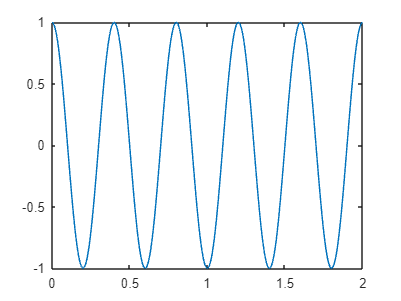

f1=@(x) cos(5*pi*x);
dibujaF(f1,0,2)

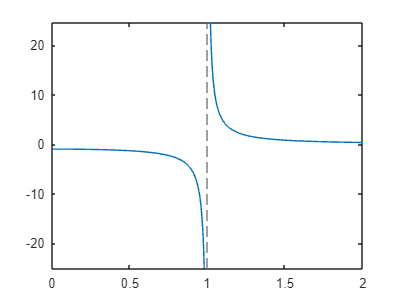

f2=@(x) 1/(x^2-1);
dibujaF(f2,0,2)

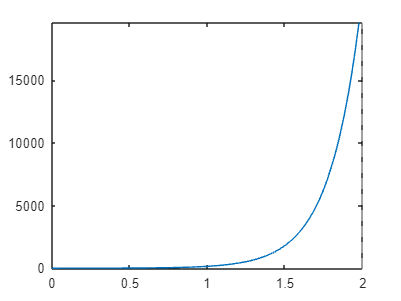

f3=@(x) exp(5*x)-1;
dibujaF(f3,0,2)

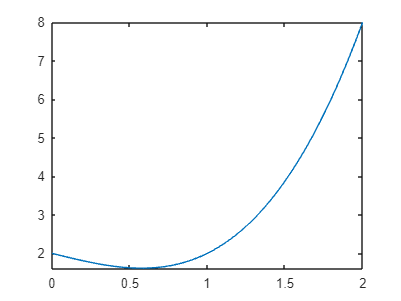

f4=@(x) x^3-x+2;
dibujaF(f4,0,2)

Construya otra figura que incluya en una sola gráfica la representación de todas las funciones anteriores cada una en un color distinto utilizando plot y hold on

subplot(221)
dibujaF(f1,0,2)
title('f_1(x)')

subplot(222)
dibujaF(f2,0,2)

title('f_2(x)')

subplot(223)
dibujaF(f3,0,2)
title('f_3(x)')

subplot(224)
dibujaF(f4,0,2)

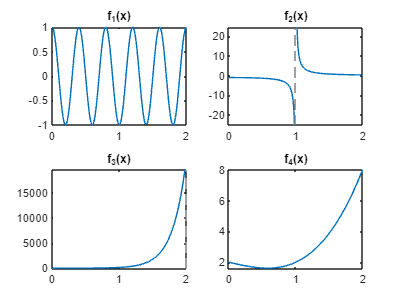

title('f_4(x)')

¿Qué figura te parece más útil? ¿Por qué?

La figura que me parece más útil es f4 al tratarse de una suma de polinomios de distinto grado, que puede ser una función común a la hora de operar, pero no tiene una representación gráfica tan conocida como las demás funciones.

***Función del ejercicio 1***

function matrizA=tridiagonal(a,b,c,n)
matrizA=diag(a*ones(1,n))+diag(b*ones(1,n-1),1)+diag(c*ones(1,n-1),-1);
end

***Función del Ejercicio 4***

function []=dibujaF(f,a,b)
fplot(f,[a b])
end